# 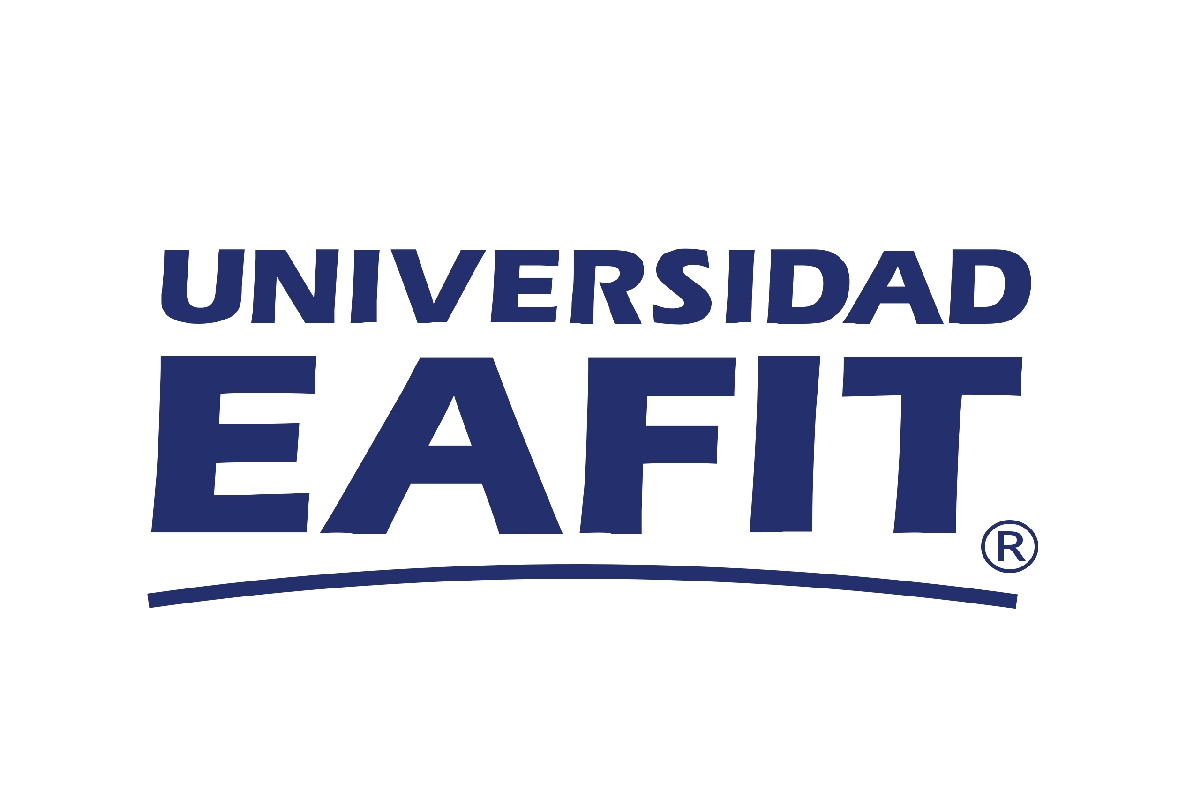                               Modelo del crecimiento de un tumor

Por Miguel Chacón y Felipe Henao, Universidad EAFIT.

## 1. Introducción 

En el desarrollo de este proyecto nos basamos en el trabajo de $\textit{De Pillis & Radunskaya (2003)}$. El modelo de este trabajo representa el crecimiento de un tumor y como es su respuesta a un tratamiento, hay diversos factores que intervienen en este proceso, principalmente la severidad de la enfermedad, la aplicación del tratamiento y la fuerza del sistema inmune del paciente.

En el modelo se incluyen células inmunitarias cuyo crecimiento puede verse afectado por la presencia del tumor, las células inmunitarias pueden destruir células tumorales por medio de un proceso cinético. También se incluyen unos términos de competencia, es decir, las células normales y las tumorales compiten por los recursos disponibles, mientras que las células inmunitarias y las tumorales compiten en una relación depredador-presa. En el modelo $ I(t)$ denota el número de células inmunitarias en el tiempo $t$, $T(t)$ el número de células tumorales o tumorales en el tiempo $t$, $N(t)$ el número de células normales, o huésped, en el tiempo t.

Se considera que la fuente de las células inmunitarias está fuera del sistema, por lo que es razonable suponer una tasa de afluencia constante s. Además, en ausencia de cualquier tumor, las células morirán a una tasa per cápita d1, lo que resulta en un tamaño de población a largo plazo de s/$d_1
$ células.

La presencia de células tumorales estimula la respuesta inmunitaria, representada por el término de crecimiento no lineal positivo de las células inmunitarias


$$\frac{\rho I(t)T(t)}{\alpha + T(t)}$$


$\rho$ y $\alpha$ son constantes positivas.

La reacción de las células inmunes y tumorales puede resultar en la muerte de las células tumorales o en la inactivación de las células inmunes, representadas por los dos términos de competición

$\frac{dI}{dt} = -c_1I(t)T(t) $ y $\frac{dT}{dt} = -c_2I(t)T(t)$

Tanto las células tumorales como las normales se modelan mediante una ley de crecimiento logística, con los parámetros $r_i$ y $b_i$ que representan las tasas de crecimiento $\textit{per cápita}$ y las capacidades de carga recíprocas de los dos tipos de células: $i = 1$ identifica los parámetros asociados al tumor, e $i = 2$ los asociados al tejido normal. Además, hay dos términos que representan la competencia entre las células tumorales y las del huésped. 

Al juntar todos los términos mencionados anteriormente se obtiene el siguiente sistema de ecuaciones diferenciales ordinarias.


$$\dot{N} = r_2 N(1-b_2N)-c_4TN$$



$$\dot{T} = r_1T(1-b_1T)-c_2IT-c_3TN$$



$$\dot{I} = s + \frac{\rho IT}{\alpha + T} -c_1IT-d_1I$$


Se añade el efecto de la droga a este sistema. Se denota por $u(t)$ la cantidad de fármaco en la zona del tumor en el momento $t
$. Además, se supone que el fármaco mata todos los tipos de células, pero que la tasa de destrucción diferente para cada tipo de célula, con una curva de respuesta en todos los casos dada por una exponencial


$$F(u) = a(1-e^{-ku})$$


$F(u)$ es la muerte celular fraccionada para una cantidad dada de fármaco $U$, en el lugar del tumor. Dado que se desconocen los detalles de la farmacocinética, se establece $ k = 1$ como en estudios preliminares. Denotamos por $a_1$, $a_2$ y $a_3$ los tres coeficientes de respuesta diferentes. Se añaden estos términos al sistema de ecuaciones diferenciales anterior, así como una ecuación para $u(t)$, la cantidad de fármaco en el lugar del tumor. Ésta viene determinada por la dosis dada $v(t)$, y una tasa de decaimiento $\textit{per cápita}$ del fármaco una vez inyectado. Esta tasa de decaimiento incorpora todas las vías de eliminación del fármaco.

El sistema con interacción de fármacos viene dado por:


$$\dot{N} = r_2 N(1-b_2N)-c_4TN - a_3(1-e^{-u})N$$



$$\dot{T} = r_1T(1-b_1T)-c_2IT-c_3TN - a_2(1-e^{-u})T$$



$$\dot{I} = s + \frac{\rho IT}{\alpha + T} -c_1IT-d_1I- a_1(1-e^{-u})I$$


### 
$$\dot{u}=v(t)-d_2u$$


### 1.1. Resumen del significado de términos

- $N(t)$: El número de células normales, o huésped, en el tiempo $t$. Se usa $N(0) = 1$

- $T(t)$: El número de células tumorales o tumorales en el tiempo $t$. Se usa $T(0) = 0.25$

- $I(t)$: Denota el número de células inmunitarias en el tiempo $t
$. Se usa $I(0) = 0.15$ y $I(0) = 0.10$

- $a_i$ : Fraccion de muerte celular, $a_3 \leq a_1 \leq a_2$.  Se usa $a_1 = 0.2$, $a_2 = 0.3 $, y $a_3 = 0.1 $

- $b_1,b_2$: capacidades de barrido, $b_1^{-1}\leq b_2^{-1} = 1$. Se usa $b_1 = b_2 = 1.0$

- $c_1,c_2,c_3,c_4$ : Terminos de competicion. Se usa $c_1 = 1.0$, $c_2 = 0.5 $, $c_3 = 1.0 $ y $c_4 = 1.0 $

- $d_1,d_2$ : tasas de muerte, $d_1$ es la tasa de muerte $\textit{per capita}$ de celulas inmunes, y $d_2$ es la tasa de muerte $\textit{per capita}$ de la droga. Se usa $d_1 = 0.2$ y $d_2 = 1.0 $

- $r_1,r_2$ : tasa por unidad de crecimiento. En el trabajo asumimos que la poblacion de celular tumorales crece mas rápido que la población de celulas normales, es decir, $r_1>r_2$. Se usa $r_1 = 1.5$ y $r_2 = 1.0$

- $s$ : Tasa de fuente inmunitaria. $0<s\leq0.5$. Se usa $s = 0.33$

- $\alpha$ : Tasa de umbral inmune. Se usa $\alpha = 0.3$

- $\rho
$ : Tasa de respuesta inmune. Se usa $\rho=0.01$, para simular un paciente con un sistema inmunologico comprometido

% Parametros
clear; clc; clf

ci=[1 0.25 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
a1=0.2; a2=0.3; a3=0.1;
b1=1.0; b2=1.0;
c1=1.0; c2=0.5; c3=1.0; c4=1.0;
d1=0.2; d2=1.0;
r1=1.5; r2=1;
s=0.33;
alpha=0.3;
rho=0.01;

### **1.2. Figura del diagrama de bloques y máscaras**

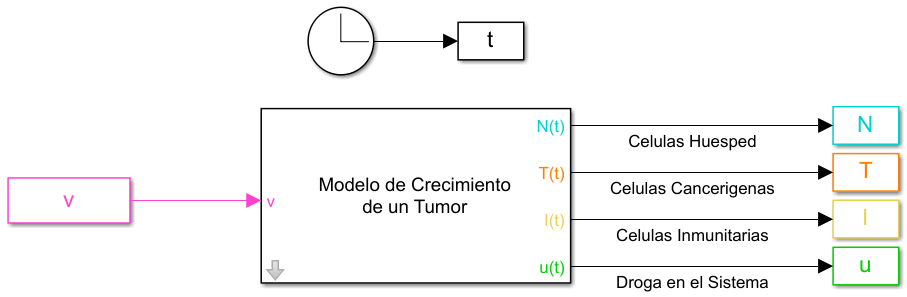

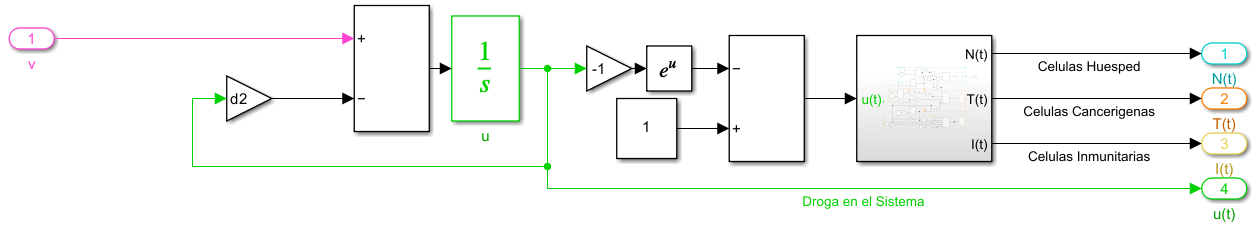

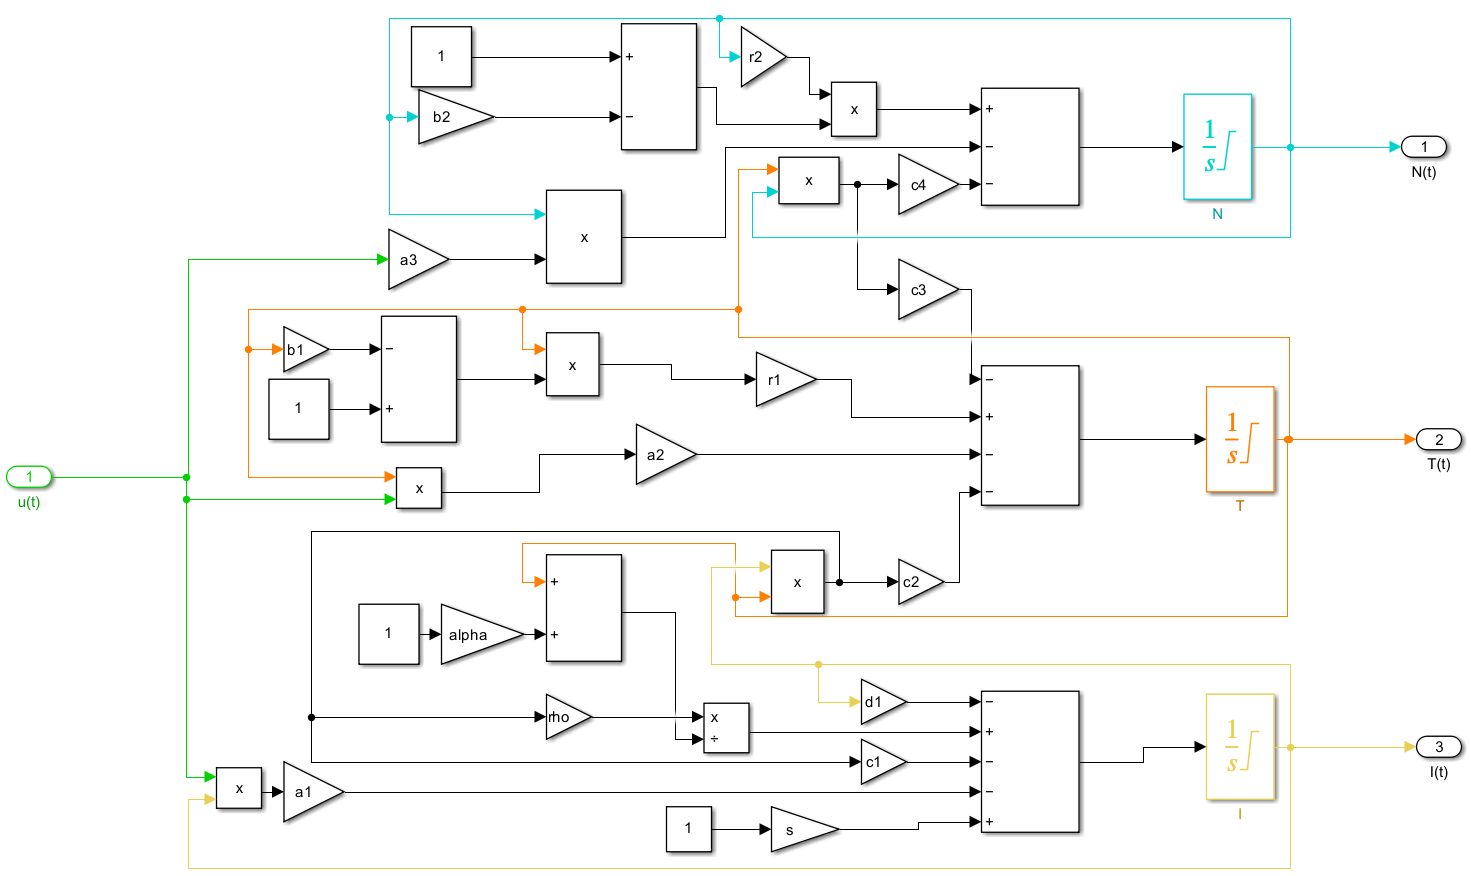

### 1.3. Hipótesis

- El modelo lineal se ajustará bien al modelo no lineal con valores cercanos al punto de operación, pero esperamos que el rango de linealidad sea bajo.

- Se espera que el rango de estabilidad para un controlador K continuo sea mayor que para el controlador K discreto.

- Los valores de ganancia k obtenidos utilizando el método de Routh-Hurwitz aseguran la estabilidad del sistema de crecimiento del tumor para los rangos de valores considerados.

## 2. Métodos

- Con base en el modelo de bloques y mascaras hecho en Simulink anteriormente, se buscará linealizar el modelo tratado alrededor de uno de sus puntos de equilibrio y se determinará el rango estabilidad en lazo cerrado con un controlador constante K tanto en tiempo continuo como en tiempo discreto.

- Para obtener el punto de equilibrio de interés, primero se dibujará la curva de linealidad del modelo, para esto se realizará múltiples simulaciones cada una con una entrada constante distinta, y se obtendrá el punto de equilibrio alcanzado con dicha entrada, el cual será después graficado teniendo como el eje X el valor de la entrada y el eje Y el valor del punto de equilibrio.

- Luego, seleccionamos un punto de equilibrio de los presentes en la gráfica para trabajar sobre ese, además, se calculará este punto de equilibrio igualando todas las ecuaciones de estado a 0 y solucionando el sistema mediante la función vpasolve de MATLAB usando la entrada escogida.

- Después de escoger el punto de equilibrio de interés, se linealizará el modelo tanto con MATLAB usando la función linmod como analíticamente, y se verá si ambos resultados coinciden, después se comparará los resultados obtenidos con el modelo no lineal y lineal al usar una entrada constante cerca y lejos del valor correspondiente punto de equilibrio escogido. Esta comparación mencionada también se hará con una entrada sinusoidal centrada en dicho valor.

- Posteriormente, se buscará el rango de estabilidad para un controlador K continuo, primero hallando la funcion de transferencia en lazo cerrado para la de variable de estado con la que se quiere trabajar y por medio del arreglo de Routh-Hurwitz se encontrara los valores de K para los cuales el modelo permanece estable. Además, se comprobará esto viendo el lugar de las raíces usando la función rlocus de MATLAB. Finalmente, se hará pruebas con el modelo no lineal para distintos valores del control K dentro y fuera del rango de estabilidad, verificando que si se estabilice para los valores de K en el rango de estabilidad y no se estabilice en el otro caso.

- A continuación, se hará el mismo procedimiento anterior pero con un controlador K en tiempo discreto. Para esto, primero se buscará un tiempo de muestreo adecuado teniendo en cuenta el tiempo de crecimiento del modelo, y se usará para discretizar la función de transferencia. Después, se hallará la función de transferencia en lazo cerrado discreta y mediante la transformación bilineal se usará el arreglo de Ruth-Hurwitz para evaluar los valores de K en que el modelo se estabiliza en el punto deseado. Similarmente, se comprobará viendo el lugar de las raíces usando la función rlocus de MATLAB y se hará simulaciones  con el modelo no lineal para distintos valores del control K discreto dentro y fuera del rango de estabilidad, verificando que si se estabilice para los valores de K en el rango de estabilidad y no se estabilice en el otro caso. 

- Finalmente, se discutirá e interpretará los resultados obtenidos para la linealización y el rango de estabilidad para un controlador constante K continuo y discreto. Adicionalmete, se hará una comparación entre los resultados obtenidos el controlador continuo y el discreto.

## 3. Resultados

### 3.1. Curva de linealidad

Primero, haremos la curva de linealidad para cada variable del sistema mediante simulación.

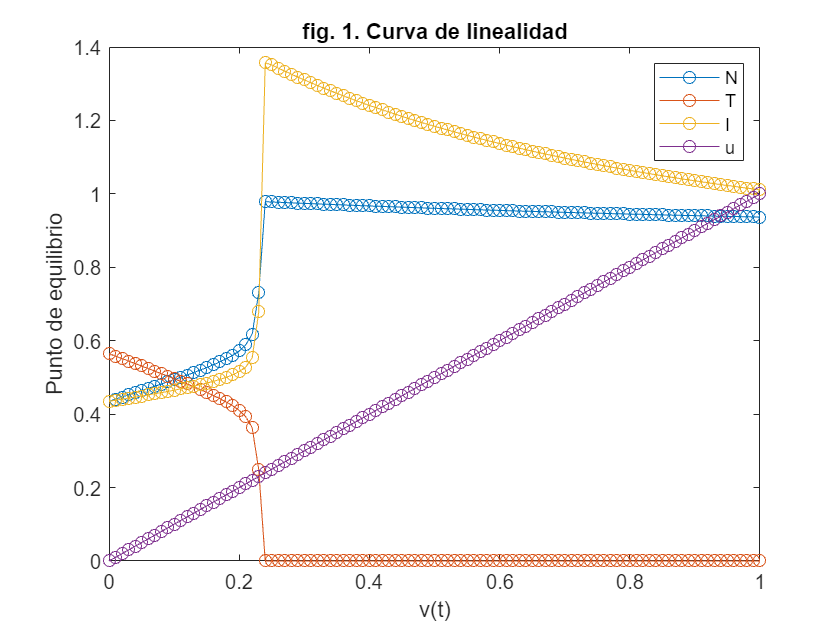

t=0:0.1:200;
vs=[t' ones(size(t,2),1)];
step=0:0.01:1;
Nf=zeros(length(step),1);
If=zeros(length(step),1);
Tf=zeros(length(step),1);
uf=zeros(length(step),1);
for i=1:length(step)
    v=vs;
    v(:,2)=step(i)*vs(:,2);
    sim("ModeloPractica")
    Nf(i)=N(end);
    Tf(i)=T(end);
    If(i)=I(end);
    uf(i)=u(end);
end
plot(step,[Nf Tf If uf],'-o')
xlabel("v(t)")
ylabel("Punto de equilibrio")
title("fig. 1. Curva de linealidad")
legend(["N", "T", "I", "u"])

En la figura 1 se puede ver la curva de linealidad de cada variable, se nota que a partir de una entrada de alrededor de 0.25 el sistema se satura por lo que solo nos enfocaremos en estudiar la linealidad cuando la entrada es menor que 0.25. Además, se puede evidenciar que la variable de estado u tiene un comportamiento lineal. Para el trabajo, buscaremos el punto de equilibrio cuando la entrada es 0.1, pues para este valor el sistema aún no se satura y se puede ver que alrededor de dicho punto hay cierto comportamiento lineal.

### 3.2. Puntos de equilibrio

A continuación, se calculara los puntos de equilibrio presentes en el sistema mediante la función vpasolve de MATLAB, teniendo una entrada constante de 0.1.

clear N I T u
syms N T I
EqP=[];
v=0.1;
u=v/d2;
eq1=r2*N*(1-b2*N)-c4*T*N-a3*(1-exp(-u))*N;
eq2=r1*T*(1-b1*T)-c2*I*T-c3*T*N-a2*(1-exp(-u))*T;
eq3=s+(rho*I*T)/(alpha+T)-c1*I*T-d1*I-a1*(1-exp(-u))*I;
Y0=vpasolve([eq1==0,eq2==0,eq3==0],[N,T,I]);

%Quitamos los puntos en los que alguno N, I o T sea negativo o imaginarios
No=[];
To=[];
Io=[];
for i=1:length(Y0.N)
    Ns=double(Y0.N(i));
    Ts=double(Y0.T(i));
    Is=double(Y0.I(i));
    if all([Ns>=0,Ts>=0,Is>=0]) && isreal([Ns Ts Is])
        No=[No Ns];
        To=[To Ts];
        Io=[Io Is];
    end
end
EqP=[EqP
    No' To' Io' u*ones(length(No),1)];
tab=array2table(EqP,'VariableNames',{'N','T','I','u'});
disp(tab)

      N         T         I        u 
    ______    ______    ______    ___

    0.7433    0.2472    0.7148    0.1
         0         0    1.5066    0.1
    0.4934     0.497    0.4649    0.1
         0    0.8802    0.3023    0.1
    0.9905         0    1.5066    0.1



Esta tabla muestra los puntos de equilibrio del sitema cuando la entrada es constante con un valor de 0.1. 

Como punto de equilibrio de intéres, escogimos el punto N=0.493446, T=0.497038, I=0.464897 y u=0.1 donde la entrada es constante de 0.1. Dicho punto lo escogimos ya que las poblaciones de todos los tipos de células en el punto son positivas, esto es, todavía están presentes todos los tipos de células en el paciente. Esto nos resulta más interesante porque, debido a la naturaleza del sistema, cuando una de las poblaciones de células ya sean normales o tumorales llega a 0, esta población no vuelve a crecer y se queda estancada en 0. Además, en la curva de linealidad presentada en la figura 1, se puede evidenciar cierta linealidad alrededor del punto donde la entrada es 0.1.

### 3.3. Linealización

En primer lugar, vamos a hallar el sistema lineal de manera analitica, para esto, derivamos cada ecuacion con respecto a cada variable de estado para formar el jacobiano y luego con respecto a cada entrada. Despues, evaluamos el resutado en el punto de equilibrio escogido para hallar las matrices A y B. 

Las variables de estado en el sistema son N, T, I y u, y vamos a considerar


$$f_1 = r_2 N(1-b_2N)-c_4TN - a_3(1-e^{-u})N$$



$$f_2 = r_1T(1-b_1T)-c_2IT-c_3TN - a_2(1-e^{-u})T$$



$$f_3 = s + \frac{\rho IT}{\alpha + T} -c_1IT-d_1I- a_1(1-e^{-u})I$$



$$f_4=v(t)-d_2u$$


Derivemos cada una con respecto a N


$$\frac{\partial f_1}{\partial N} = r_2 -2r_2b_2N-c_4T - a_3(1-e^{-u})$$



$$\frac{\partial f_2}{\partial N}  =-c_3T$$



$$\frac{\partial f_3}{\partial N} =0$$



$$\frac{\partial f_4}{\partial N} =0$$


Con respecto a T


$$\frac{\partial f_1}{\partial T} =-c_4N$$



$$\frac{\partial f_2}{\partial T}  =r_1-2r_1b_1T-c_2I-c_3N- a_2(1-e^{-u})$$



$$\frac{\partial f_3}{\partial T} =\rho\frac{I(\alpha+T)-IT}{(\alpha+T)^2}-c_1I$$



$$\frac{\partial f_4}{\partial T} =0$$


Con respecto a I


$$\frac{\partial f_1}{\partial I} =0$$



$$\frac{\partial f_2}{\partial I}  =-c_2T$$



$$\frac{\partial f_3}{\partial I} =\frac{\rho T}{\alpha+T}-c_1T-d_1-a_1(1-e^{-u})$$



$$\frac{\partial f_4}{\partial I} =0$$


Y finalmente con respecto a u


$$\frac{\partial f_1}{\partial u} = -a_3Ne^{-u}$$



$$\frac{\partial f_2}{\partial u}  = -a_2Te^{-u}$$



$$\frac{\partial f_3}{\partial u} = -a_1Ie^{-u}$$



$$\frac{\partial f_4}{\partial u} =-d2$$


Luego, definiendo $p_0$ como el punto de equilibrio, la matriz A esta dada por


$$A=\left.\pmatrix{\frac{\partial f_1}{\partial N} & \frac{\partial f_1}{\partial T} & \frac{\partial f_1}{\partial I} & \frac{\partial f_1}{\partial u}
\cr \frac{\partial f_2}{\partial N} & \frac{\partial f_2}{\partial T} & \frac{\partial f_2}{\partial I} & \frac{\partial f_2}{\partial u}
 \cr \frac{\partial f_3}{\partial N} & \frac{\partial f_3}{\partial T} & \frac{\partial f_3}{\partial I} & \frac{\partial f_3}{\partial u}
\cr \frac{\partial f_4}{\partial N} & \frac{\partial f_4}{\partial T} & \frac{\partial f_4}{\partial I} & \frac{\partial f_4}{\partial u} }\right \vert_{p_0}=
\pmatrix{-0.49345 & -0.49345 & 0 & -0.04465
\cr -0.49704 & -0.74556 & -0.24852 & -0.13492
\cr 0 & -0.46270 & -0.70983 & -0.08413
\cr 0 & 0 & 0 & -1}$$


y la matriz, o en este caso vector ya que es solo una entrada, B esta dada por:


$$B=\left.\pmatrix{\frac{\partial f_1}{\partial u}  \cr \frac{\partial f_2}{\partial u}  \cr \frac{\partial f_3}{\partial u}  \cr \frac{\partial f_4}{\partial u} }\right \vert_{p_0}=\pmatrix{0 \cr 0 \cr 0 \cr 1}$$


Ahora, usando la función linmod de MATLAB, se va a linealizar el sistema alrededor del punto de equilibrio escogido, con una entrada constante de 0.1.

t=0:0.1:150; 
v=[t' zeros(size(t,2),1)];
x=[0.493446210665051 0.497037531138545 0.464897436075839 0.10]';
[A,B,C,D]=linmod('ModeloPractica',x,0.1);

El sistema lineal esta dado por las siguientes matrices donde $x_1=\Delta N$, $x_2=\Delta T$, $x_3=\Delta I$ y $x_4=\Delta u$

sys=ss(A,B,C,D)

sys =
 
  A = 
             x1        x2        x3        x4
   x1   -0.4934   -0.4934         0  -0.04465
   x2    -0.497   -0.7456   -0.2485   -0.1349
   x3         0   -0.4627   -0.7098  -0.08413
   x4         0         0         0        -1
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.


Para la función de transferencia, escogimos la variable T, ya que nos parece que es la mas relevante estudiar, aunque las otras tambien son importantes, ya que queremos conocer como es el crecimiento del tumor y su estabilidad. Luego, la funcion de transferencia es la siguiente:

sysL=ss(A,B,[zeros(1,4);0,1,0,0;zeros(2,4)],D);
G=tf(sysL);
G=G(2)

G =
 
          -0.1349 s^2 - 0.1192 s - 0.02119
  ------------------------------------------------
  s^4 + 2.949 s^3 + 2.836 s^2 + 0.9174 s + 0.03031
 
Continuous-time transfer function.
Model Properties


### 3.4. Comparación entre la aproximación lineal y el modelo no lineal

Como se menciono en los metodos, se va a realizar una comparación de la salida entre el modelo lineal obtenido y el no lineal.

#### 3.4.1. Con entrada constante

Primero, se hará esta comparación al tener una entrada constante cerca y lejos del valor del punto de equilibrio escogido.

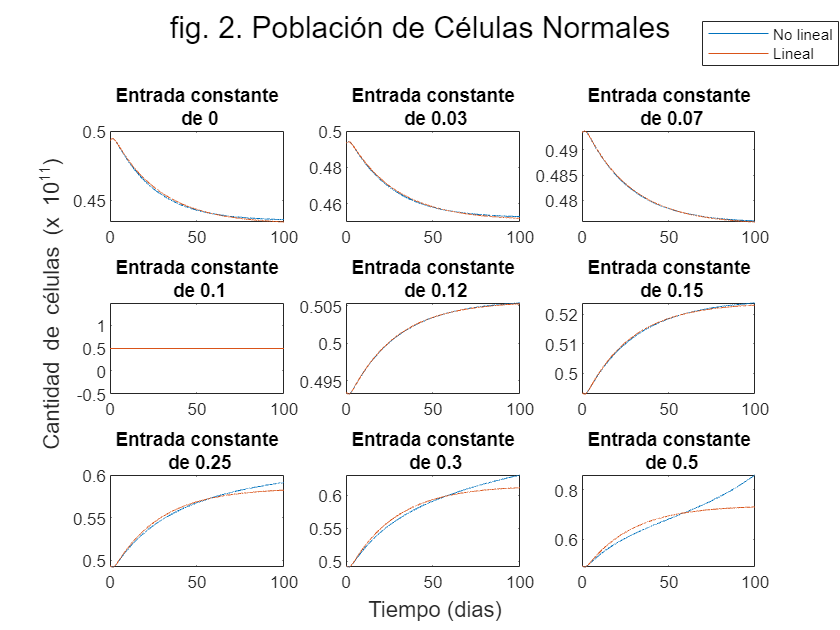

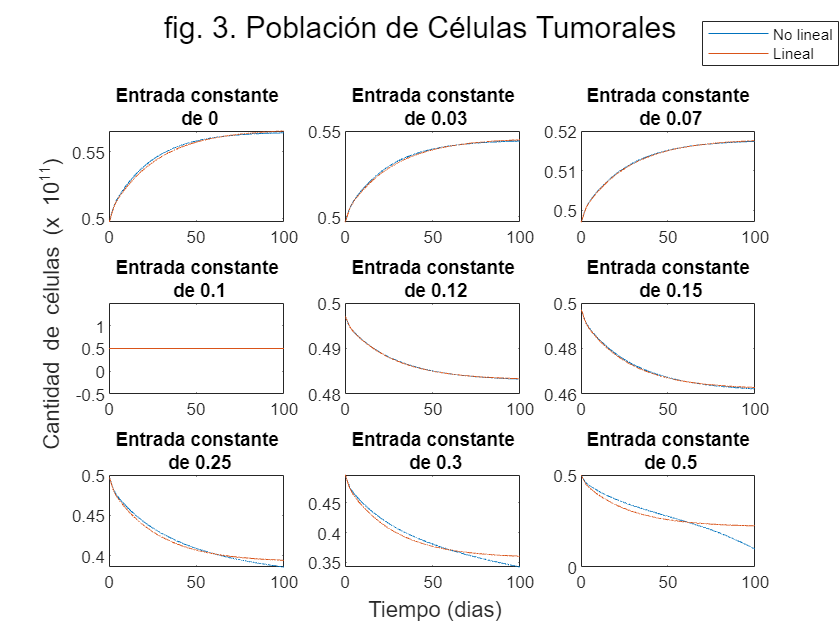

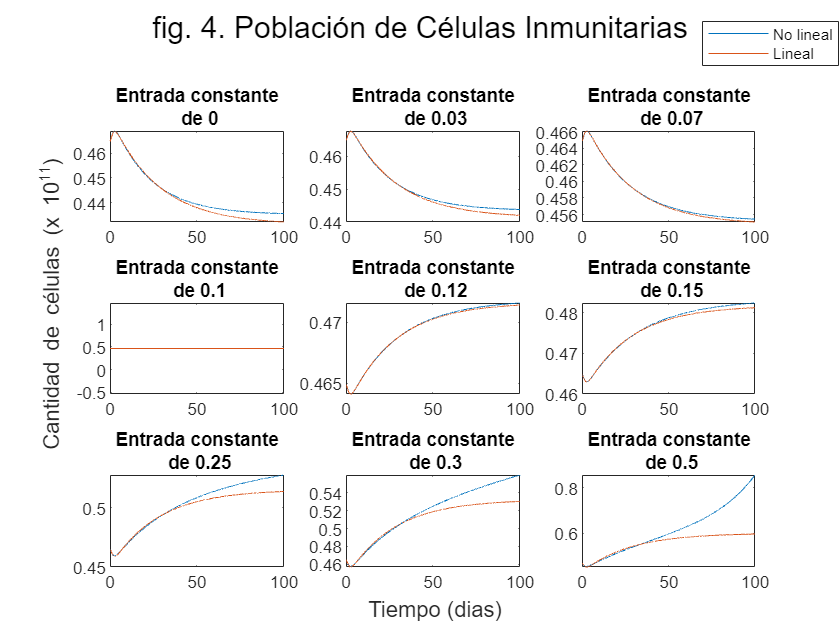

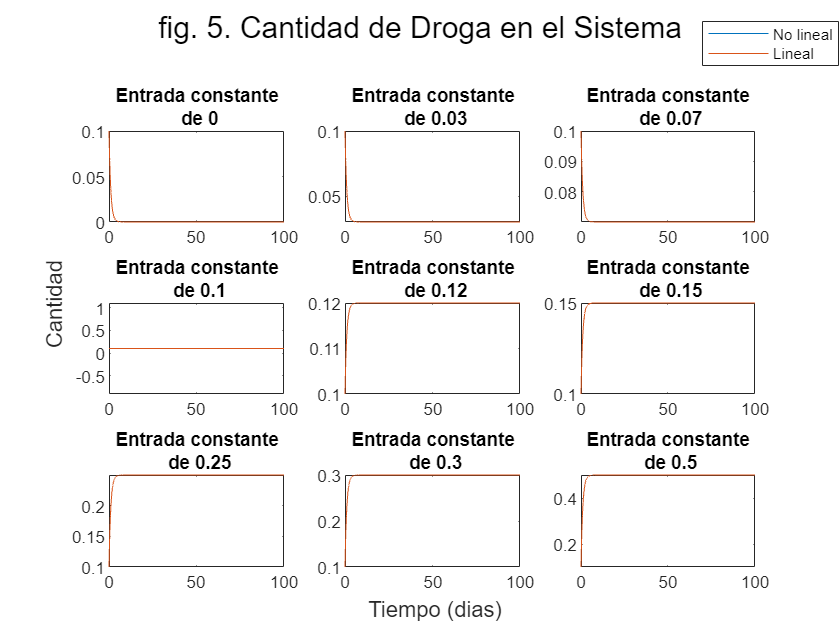

t=0:0.01:100;
t=t';
entradas=[0 0.03 0.07 0.1 0.12 0.15 0.25 0.3 0.5];
for i=1:length(entradas)
    v=[t entradas(i)*ones(length(t),1)];
    sim("Modelos_paralelo")
    figure(1)
    subplot(3,3,i)
    plot(t,N)
    title(["Entrada constante"," de "+string(entradas(i))])    
    figure(2)
    subplot(3,3,i)
    plot(t,T)
    title(["Entrada constante"," de "+string(entradas(i))])
    figure(3)
    subplot(3,3,i)
    plot(t,I)
    title(["Entrada constante"," de "+string(entradas(i))])
    figure(4)
    subplot(3,3,i)
    plot(t,u)
    title(["Entrada constante"," de "+string(entradas(i))])
end

figure(1)
sgtitle("fig. 2. Población de Células Normales");
figure(2)
sgtitle("fig. 3. Población de Células Tumorales");
figure(3)
sgtitle("fig. 4. Población de Células Inmunitarias");
figure(4)
sgtitle("fig. 5. Cantidad de Droga en el Sistema");

for i=1:4
    fig=figure(i);
    Lgnd = legend('show');
    Lgnd.Position(1) = 0.85;
    Lgnd.Position(2) = 0.9;
    legend(["No lineal","Lineal"])
    han=axes(fig,'visible','off'); 
    han.Title.Visible='on';
    han.XLabel.Visible='on';
    han.YLabel.Visible='on';
    xlabel("Tiempo (dias)")
    if i==4
        ylabel("Cantidad")
    else
        ylabel("Cantidad de células (x 10^{11})")
    end
end

Las figuras 2 a 5 muestan las poblaciones de celulas normales, tumorales e inmunitarias y la cantidad presente en el sistema obtenidas del modelo lineal presentado anteriormente y el modelo no lineal al usar una entrada constante de distintos valores. Es posible ver que, en general, para las entradas menores a 0.2 hay una buena aproximación del modelo lineal al no lineal, sin embargo, para la población de celulas inmunitarias ya con una entrada de 0.07 se puede ver que ya se empieza a alejar el modelo lineal del no lineal. Finalmente, se evidencia que el ajuste del modelo lineal a la cantidad de droga en el sistema es altamente preciso a lo obtenido en el modelo no lineal.

#### 3.4.2. Con entrada sinusoidal

Ahora, se hará la comparación al tener una entrada sinusoidal centrada en el valor del punto de equilibrio escogido con distintas amplitudes.

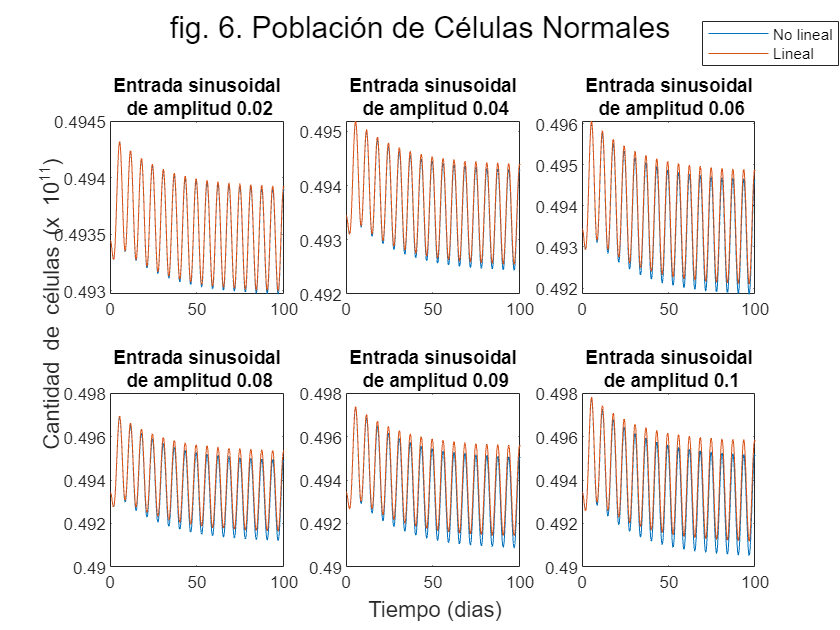

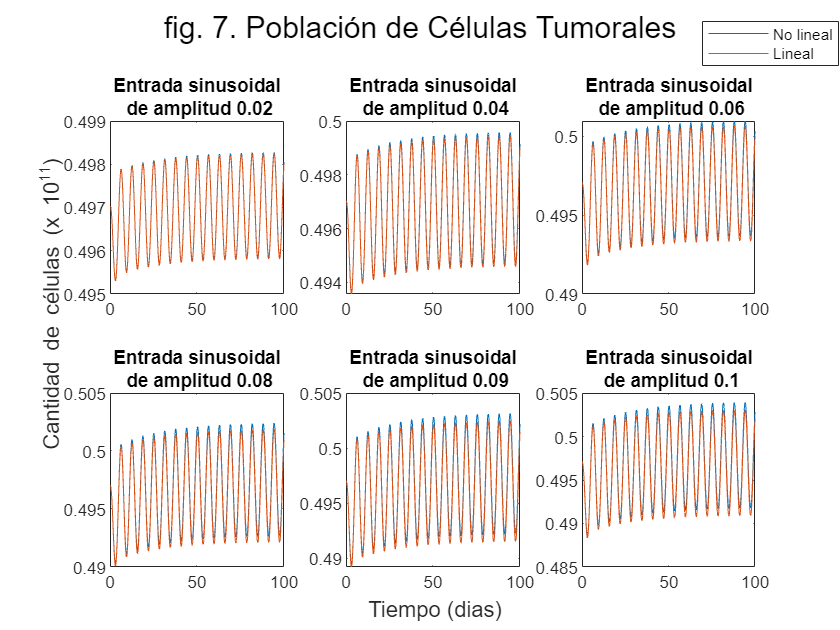

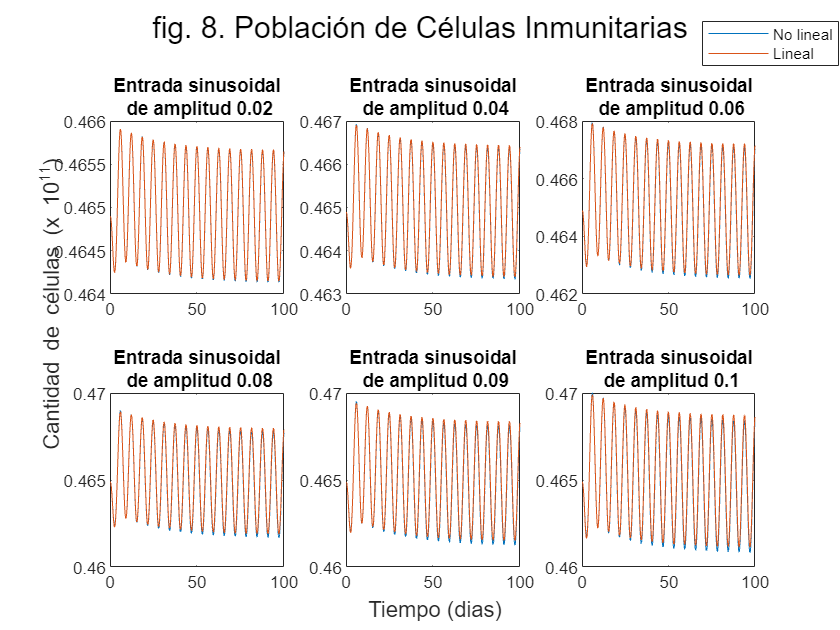

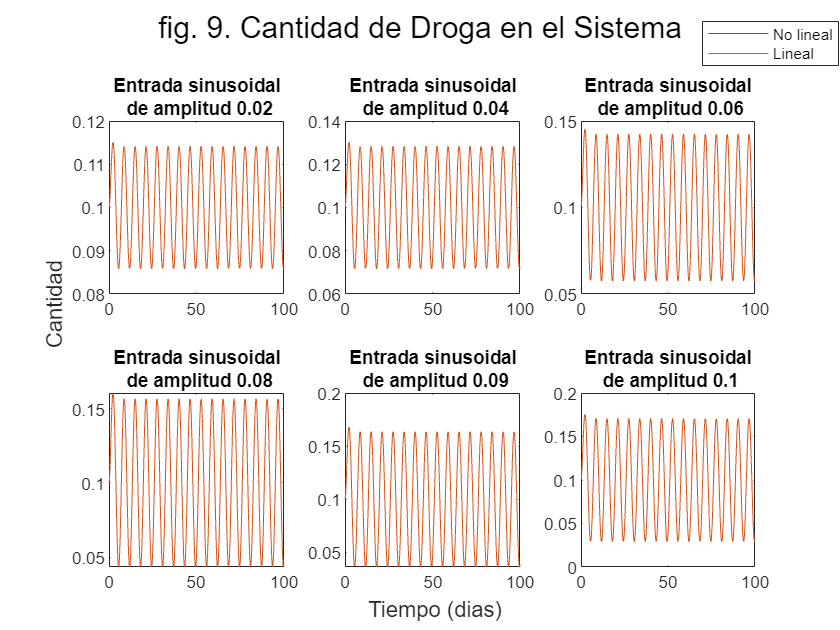

amplitudes=[0.02 0.04 0.06 0.08 0.09 0.1];
for i=1:length(amplitudes)
    v=[t 0.1+amplitudes(i)*sin(t)];
    sim("Modelos_paralelo")
    figure(1)
    subplot(2,3,i)
    plot(t,N)
    title(["Entrada sinusoidal"," de amplitud "+string(amplitudes(i))])   
    figure(2)
    subplot(2,3,i)
    plot(t,T)
    title(["Entrada sinusoidal"," de amplitud "+string(amplitudes(i))])
    figure(3)
    subplot(2,3,i)
    plot(t,I)
    title(["Entrada sinusoidal"," de amplitud "+string(amplitudes(i))])
    figure(4)
    subplot(2,3,i)
    plot(t,u)
    title(["Entrada sinusoidal"," de amplitud "+string(amplitudes(i))])
end

figure(1)
sgtitle("fig. 6. Población de Células Normales");
figure(2)
sgtitle("fig. 7. Población de Células Tumorales");
figure(3)
sgtitle("fig. 8. Población de Células Inmunitarias");
figure(4)
sgtitle("fig. 9. Cantidad de Droga en el Sistema");

for i=1:4
    fig=figure(i);
    Lgnd = legend('show');
    Lgnd.Position(1) = 0.85;
    Lgnd.Position(2) = 0.9;
    legend(["No lineal","Lineal"])
    han=axes(fig,'visible','off'); 
    han.Title.Visible='on';
    han.XLabel.Visible='on';
    han.YLabel.Visible='on';
    xlabel("Tiempo (dias)")
    if i==4
        ylabel("Cantidad")
    else
        ylabel("Cantidad de células (x 10^{11})")
    end
end

Las figuras 6 a 9 muestan las poblaciones de celulas normales, tumorales e inmunitarias y la cantidad presente en el sistema obtenidas del modelo lineal presentado anteriormente y el modelo no lineal al usar una entrada sinusoidal de distintas amplitudes. Podemos ver que para las amplitudes menores el ajuste del modelo lineal al no lineal es bastante bueno, sin embargo para valores mayores a 0.06 ya se puede ver cierta diferencia entre los resultados del lineal y el no lineal. Además, como con la entrada constante, se puede ver un ajuste preciso para la cantidad de droga en el sistema.

### **3.5. Estabilidad**

Ahora, se usará un controlador constante K con el fin de encontrar el rango de estabilidad en lazo cerrado para la función de tranferencia correspondiente a la variable T, esto se hará usando un controlador continuo y uno discreto discretizando la función de transferencia.

#### **3.5.1 Rango de estabilidad en lazo cerrado con un controlador constante K** 

La función de transferencia es 

clf
r=0;
G

G =
 
          -0.1349 s^2 - 0.1192 s - 0.02119
  ------------------------------------------------
  s^4 + 2.949 s^3 + 2.836 s^2 + 0.9174 s + 0.03031
 
Continuous-time transfer function.
Model Properties


Los polos de esta función de transferencia son

pole(G)

ans =    -1.2681
   -1.0000
   -0.6436
   -0.0371


Como todos estan en el semiplano izquierdo entonces el sistema correspondiente a la función de transferencia es estable, y los ceros son

zero(G)

ans =    -0.6375
   -0.2463


Por tanto tiene dos ceros finitos y dos infinitos.

**Arreglo de Routh-Hurwitz**

Ahora, con el fin de ver los valores de K con los cuales el modelo es estable, se encontrará la función de transferencia en lazo cerrado y usando el arreglo de Routh-Hurwitz evaluaremos los valores de K para los cuales el sistema es estable.

La función de transferencia en lazo cerrado para el sistema, siendo $G(s)$ la función de transferencia presentada anteriormente, esta dada por


$$G_{lc}(s)=\frac{KG(s)}{1+KG(s)}$$


Al reemplazar $G(s)$ y simplificar la expresión, la función de transferencia en lazo cerrado que obtenemos es:


$$G_{lc}(s)=\frac{-0.1349Ks^2-0.1192Ks-0.02119K}{s^4+2.949s^3+(2.836-0.1349K)s^2+(0.9174-0.1192K)s+(0.03031-0.02119K)}$$


Como nos interesa evaluar la estabilidad del sistema, usaremos el arreglo de Routh-Hurwitz para el polinomio del denominador, el cual corresponde a los polos, así, veremos que valores puede tomar K de tal manera que el sistema sea estable, esto es, los polos estan en el semi-plano izquierdo.

sympref('FloatingPointOutput',true);
syms K
aa0=1; aa1=2.949; aa2=2.836-0.1349*K; aa3=0.9174-0.1192*K; aa4=0.03031-0.02119*K;
RHarr=vpa([aa0,aa2,aa4;aa1,aa3,0]);
b1=det([RHarr(1,1),RHarr(1,2);RHarr(2,1),RHarr(2,2)])/-RHarr(2,1);
b2=det([RHarr(1,1),RHarr(1,3);RHarr(2,1),RHarr(2,3)])/-RHarr(2,1);
RHarr=[RHarr;b1,b2,0];
c1=det([RHarr(2,1),RHarr(2,2);RHarr(3,1),RHarr(3,2)])/-RHarr(3,1);
RHarr=[RHarr;c1,0,0];
d1=det([RHarr(3,1),RHarr(3,2);RHarr(4,1),RHarr(4,2)])/-RHarr(4,1);
RHarr=[RHarr;d1,0,0];
simplify(RHarr)

$$ans = \left(\begin{array}{ccc} 1 & 2.8360-0.1349\,K & 0.0303-0.0212\,K\\ 2.9490 & 0.9174-0.1192\,K & 0\\ 2.5249-0.0945\,K & 0.0303-0.0212\,K & 0\\ -\frac{1\,\left(1.1262e+32\,K^{2}-3.2516e+33\,K+2.2270e+34\right)}{9.4480e+32\,K-2.5249e+34} & 0 & 0\\ 0.0303-0.0212\,K & 0 & 0 \end{array}\right)$$

A partir del arreglo de Ruth-Hurwitz, por medio de la condición suficiente, la cual es que la primera columna sea mayor a 0. De esto obtenemos que:


$$2.5249-0.0945K>0\\
0.0945K<2.5249\\
K<26.7185$$



$$-0.011262K^2+0.32516K-2.2270>0\\
K<11.1717$$



$$0.0303-0.0212K>0\\
0.0212K<0.0303\\
K<1.4292$$


De lo anterior, para que el modelo sea estable el valor de K debe ser menor a 1.4292.

**Comprobación usando la función rlocus de MATLAB**

Usando la función rlocus de MATLAB obtenemos el lugar de las raíces, así, podemos verificar los valores de K que mantienen todas las raíces en el semiplano izquierdo, esto es, que el sistema sea estable.

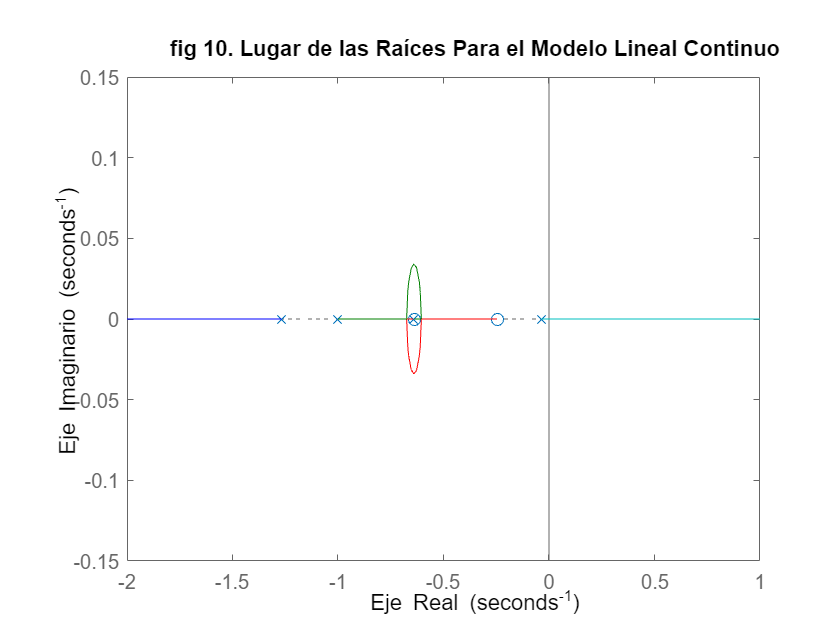

rlocus(G)
title("fig 10. Lugar de las Raíces Para el Modelo Lineal Continuo")
xlabel("Eje Real")
ylabel("Eje Imaginario")

A partir de la figura 10, podemos ver el lugar de las raíces del sistema, aqui se evidencia que tiene dos ceros finitos y dos infinitos, y los valores de K que permanecen el sistema estable son aquellos menores a 1.43.

**Comprobación con el modelo**

Ahora, usaremos el modelo para verificar que para los valores de K obtenidos el modelo si se estabiliza. Para esto movemos las condiciones iniciales cerca y lejos del punto de equilibrio y evaluamos con distintos valores de K.

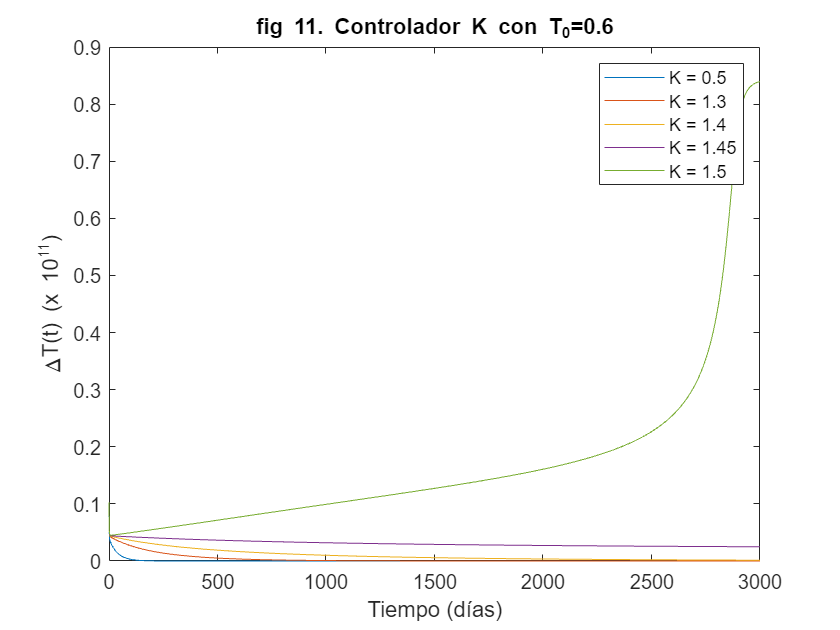

clear K
%ci=[0.493446210665051 0.497037531138545 0.464897436075839 0.10];
ci=[0.493446210665051 0.6 0.464897436075839 0.10];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
veq=0.1;
Teq=0.497037531138545;
Kval=[0.5, 1.3, 1.4, 1.45, 1.5];
for i=1:length(Kval)
    K=Kval(i);
    sim("ControladorK")
    plot(t,y)
    hold on
end
xlabel("Tiempo (días)")
ylabel("\DeltaT(t) (x 10^{11})")
title("fig 11. Controlador K con T_0=0.6")
legend("K = "+string(Kval))
hold off

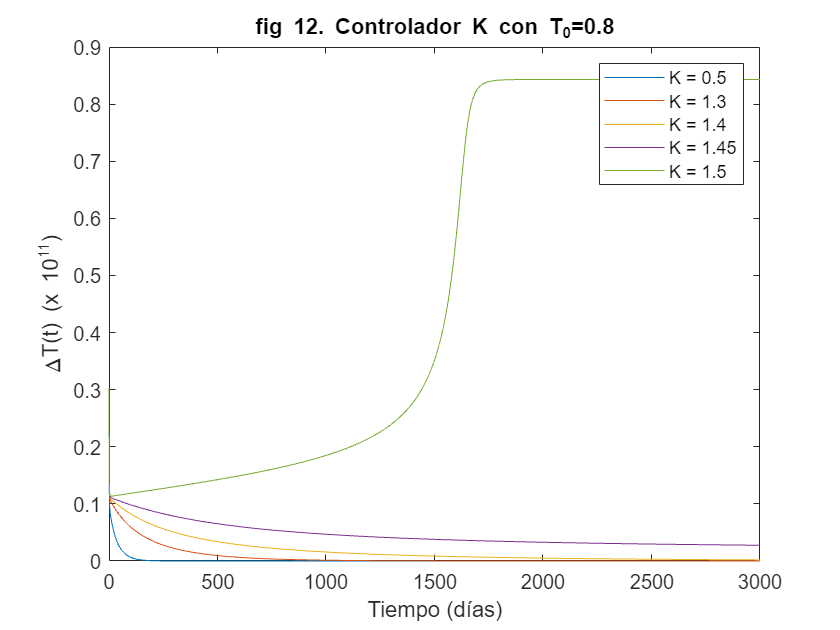

ci=[0.493446210665051 0.8 0.464897436075839 0.10];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
for i=1:length(Kval)
    K=Kval(i);
    sim("ControladorK")
    plot(t,y)
    hold on
end
xlabel("Tiempo (días)")
ylabel("\DeltaT(t) (x 10^{11})")
title("fig 12. Controlador K con T_0=0.8")
legend("K = "+string(Kval))
hold off

#### **3.5.2. Estabilidad con un controlador constante K de tiempo discreto**

**Tiempo de muestreo**

Primero, hallaremos un tiempo de muestreo adecuado usando el tiempo de crecimiento de la variable T

clear step
ci=[1 0.25 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
t=0:0.1:200;
v=[t' 0.1*ones(length(t),1)];
sim("ModeloPractica")

La siguiente figura muestra el crecimiento de la variable T, lo que se usa para hallar el tiempo de crecimiento y tiempo de muestreo

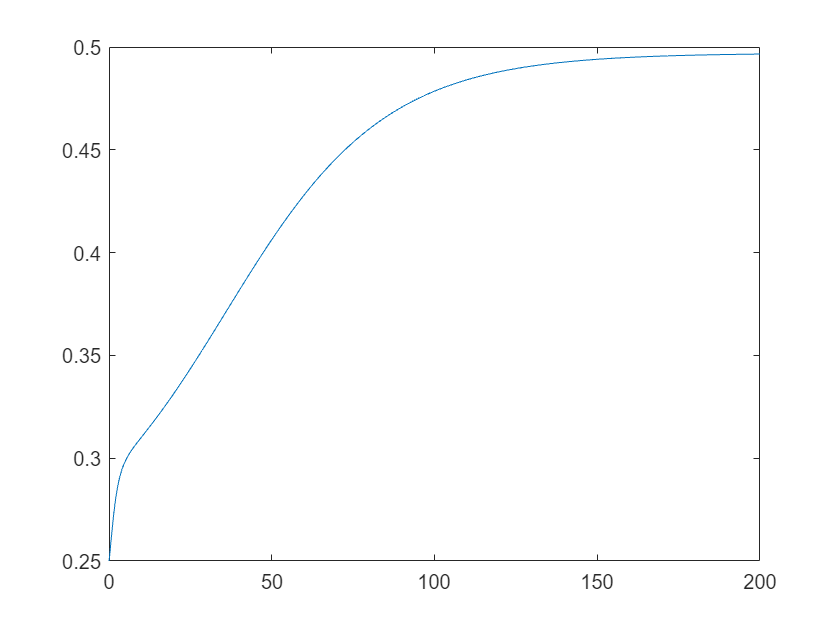

plot(t,T)

T=round(T,3);
peq=T(end);
eq=find(T==peq,1,'first');
dif=peq-T0;
t1=find(T-T0>=0.1*dif,1,'first');
t1=t(t1)

t1 = 1.6000

t2=find(T-T0>=0.9*dif,1,'first');
t2=t(t2)

t2 = 92

tr=t2-t1

tr = 90.4000

Ts=round(tr/10,1)

Ts = 9

Luego el tiempo de muestreo usado para la discretización del modelo es de 9 dias.

Para usar un controlador discreto, primero dicretizamos la función de transferencia.

Gd=c2d(G,Ts)

Gd =
 
     -0.2446 z^3 + 0.04672 z^2 - 0.0001219 z - 7.999e-08
  ---------------------------------------------------------
  z^4 - 0.7191 z^3 + 0.002281 z^2 - 2.947e-07 z + 2.979e-12
 
Sample time: 9 seconds
Discrete-time transfer function.
Model Properties


Los polos de la función de transferencia discreta son

pole(Gd)

ans =     0.7159
    0.0031
    0.0001
    0.0000


Como todos se encuentran en el circulo unitario, entonces el sistema es estable, y los ceros finitos son

zero(Gd)

ans =     0.1884
    0.0032
   -0.0005


Luego tiene tres ceros finitos y uno infinito.

Ahora hallamos la función de transferencia en lazo cerrado usando


$$G_{lc}(z)=\frac{KG(z)}{1+KG(z)}$$


Al reemplazar $G(z)$ y simplificar la expresión, la función de transferencia en lazo cerrado que obtenemos es:


$$G_{lc}(z)=\frac{K(-0.2446z^3+0.04672z^2-0.0001219z-7.999*10^{-8}}{z^4-(0.2446K+0.7191)z^3+(0.0467K+0.0023)z^2-(1.2186*10^{-4}K+2.9469*10^{-7})z+2.9790*10^{-12}-7.9991*10^{-8}K}$$


Luego, para hacer uso del arreglo de Ruth-Hurwitz usamos la transformación bilineal, esta es


$$z=\frac{1+w}{1-w}$$


lo cual al reemplazar y simplificar nos queda


$$G_{lc}(w)=\frac{0.2914Kw^4 + 0.4889Kw^3 - 0.0934Kw^2 - 0.4889Kw - 0.1980K}{(0.2914K + 1.7214)w^4 + (0.4889K + 5.4382)w^3 + (5.9954 - 0.0934K)w^2 + (2.5618 - 0.4889K)w - (0.1980K - 0.2832)}$$


sympref('FloatingPointOutput',true);
syms K
aa0=(0.2914*K + 1.7214); aa1=(0.4889*K + 5.4382); aa2=(5.9954 - 0.0934*K); aa3=(2.5618 - 0.4889*K); aa4=-(0.1980*K - 0.2832);
RHarr=vpa([aa0,aa2,aa4;aa1,aa3,0]);
b1=det([RHarr(1,1),RHarr(1,2);RHarr(2,1),RHarr(2,2)])/-RHarr(2,1);
b2=det([RHarr(1,1),RHarr(1,3);RHarr(2,1),RHarr(2,3)])/-RHarr(2,1);
RHarr=[RHarr;b1,b2,0];
c1=det([RHarr(2,1),RHarr(2,2);RHarr(3,1),RHarr(3,2)])/-RHarr(3,1);
RHarr=[RHarr;c1,0,0];
d1=det([RHarr(3,1),RHarr(3,2);RHarr(4,1),RHarr(4,2)])/-RHarr(4,1);
RHarr=[RHarr;d1,0,0];
simplify(RHarr)

$$ans = \left(\begin{array}{ccc} 0.2914\,K+1.7214 & 5.9954-0.0934\,K & 0.2832-0.1980\,K\\ 0.4889\,K+5.4382 & 2.5618-0.4889\,K & 0\\ \frac{0.0968\,K^{2}+2.5183\,K+28.1943}{0.4889\,K+5.4382} & 0.2832-0.1980\,K & 0\\ \frac{48890\,K^{2}-74576180\,K+1.5963e+09}{2420055\,K^{2}+62957678\,K+704857544} & 0 & 0\\ 0.2832-0.1980\,K & 0 & 0 \end{array}\right)$$

A partir del arreglo de Ruth-Hurwitz, por medio de la condición suficiente, la cual es que la primera columna sea mayor a 0. De esto obtenemos que:


$$0.2914K + 1.7214>0\\
0.2914K>- 1.7214\\
K>-5.9073$$



$$0.4889K + 5.4382>0\\
0.4889K >- 5.4382\\
K>-11.1233$$



$$0.0968K^2 + 2.5183K + 28.1943>0$$


Para $K\geq0$ esta ecuación siempre es mayor a 0.


$$0.000048890K^2 - 0.07458K +1.5963>0$$


$K<21.7129$ o $K>1503.8$


$$0.2832-0.1980K>0\\
-0.1980K>-0.2832\\
0.1980K<0.2832\\
K<1.4303$$


De lo anterior, para que el modelo sea estable el valor de K debe ser menor a 1.4303, el cual es prácticamente igual al obtenido para el continuo.

**Comprobación usando la función rlocus de MATLAB**

Similar a como fue hecho con el continuo, se usara rlocus para verificar el valor de K obtenido.

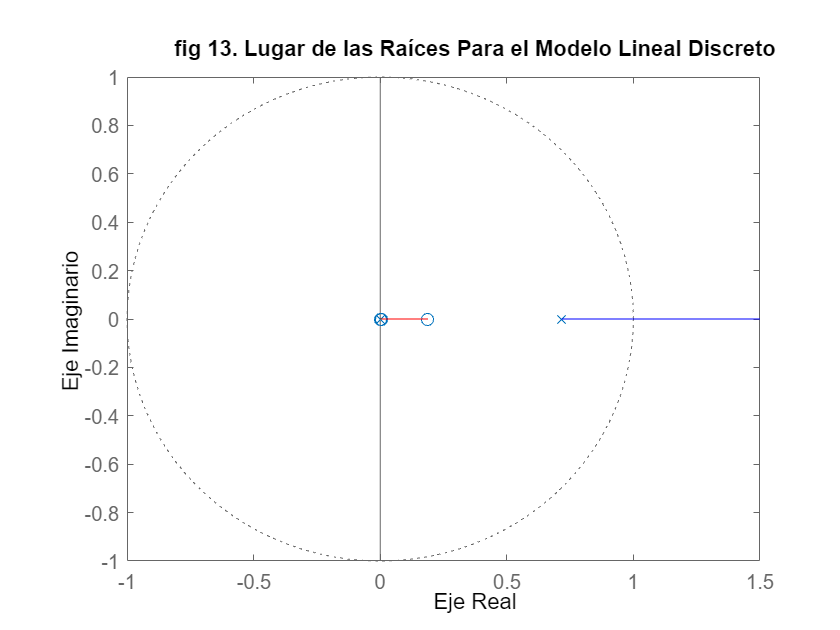

rlocus(Gd)
title("fig 13. Lugar de las Raíces Para el Modelo Lineal Discreto")
xlabel("Eje Real")
ylabel("Eje Imaginario")

A partir de la figura 13, podemos ver el lugar de las raíces del sistema discreto, en esta se evidencia que tiene tres ceros finitos y uno infinitos, y los valores de K que permanecen el sistema estable son aquellos menores a 1.43. 

**Comprobación con el modelo**

Ahora, usaremos el modelo para verificar que para los valores de K obtenidos el modelo si se estabiliza. Para esto movemos las condiciones iniciales cerca y lejos del punto de equilibrio y evaluamos con distintos valores de K.

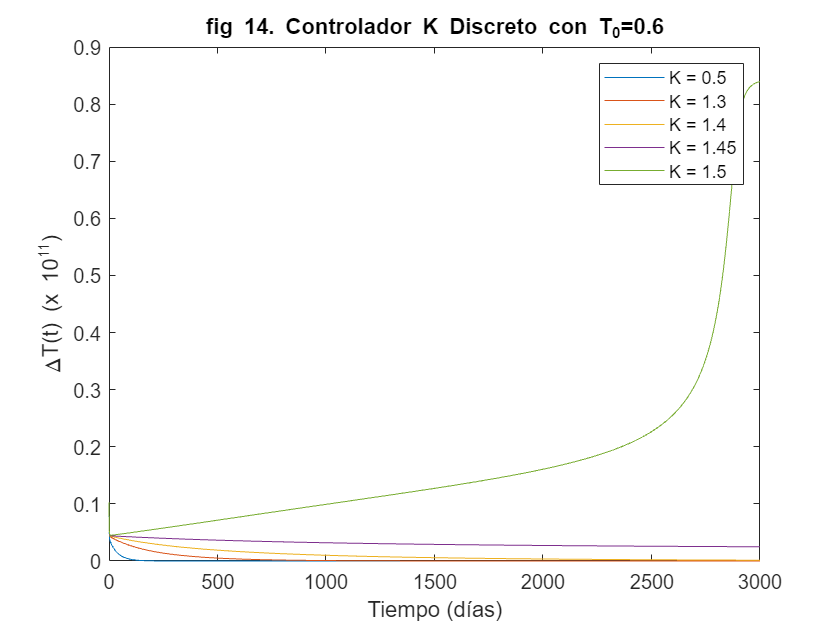

clear K
%ci=[0.493446210665051 0.497037531138545 0.464897436075839 0.10];
ci=[0.493446210665051 0.6 0.464897436075839 0.10];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
veq=0.1;
Teq=0.497037531138545;
Kval=[0.5, 1.3, 1.4, 1.45, 1.5];
for i=1:length(Kval)
    K=Kval(i);
    sim("ControladorK")
    plot(t,y)
    hold on
end
xlabel("Tiempo (días)")
ylabel("\DeltaT(t) (x 10^{11})")
title("fig 14. Controlador K Discreto con T_0=0.6")
legend("K = "+string(Kval))
hold off

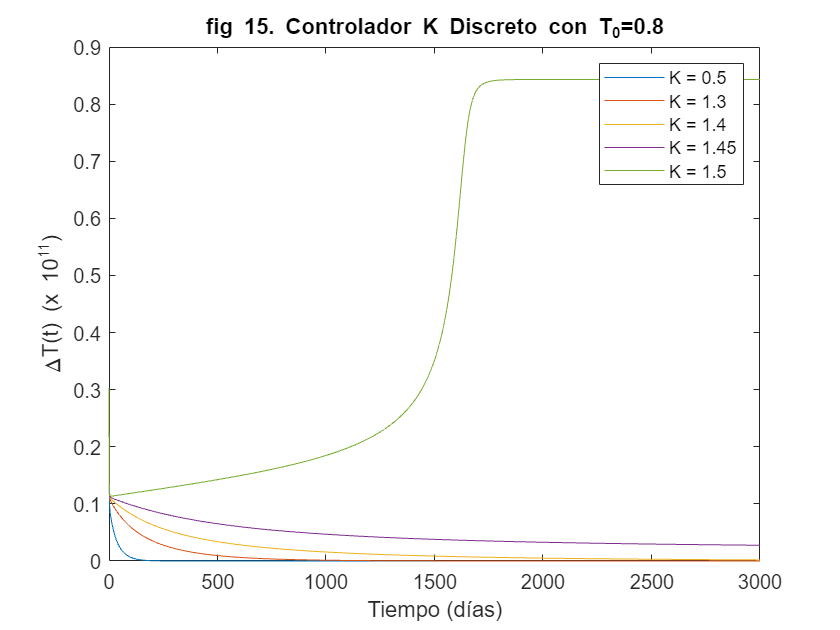


ci=[0.493446210665051 0.8 0.464897436075839 0.10];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
for i=1:length(Kval)
    K=Kval(i);
    sim("ControladorK")
    plot(t,y)
    hold on
end
xlabel("Tiempo (días)")
ylabel("\DeltaT(t) (x 10^{11})")
title("fig 15. Controlador K Discreto con T_0=0.8")
legend("K = "+string(Kval))
hold off

## 4. Discusión

### 4.1. Curva de linealidad

Como fue mencionado anteriormente, se ve en la figura 1, la cual corresponde a la curva de linealidad, que el comportamiento de la cantidad de droga en el sistema (u) es lineal, lo cual también es claro en la ecuación de estado correspondiente a esta variable, esta es $\dot{u}=v(t)-d_2u$, donde $v(t)$ es la entrada y $d_2
$ es un parámetro. 

### 4.2. Linealización

En primer lugar, se puede ver que las matrices A y B obtenidas analaliticamente al linealizar el sistema alrededor del punto de equilibrio escogido son iguales a las obtenidas haciendo uso de la funcion linmod de MATLAB, por tanto estas son las matrices usadas.

#### 4.2.1. Aproximación lineal al modelo no lineal 

Con base en la aproximación del modelo lineal, podemos concluir que, de acuerdo a los resultados vistos en las figuras 2 a 9, el modelo lineal tiene resultados casi iguales al no lineal para valores de la entrada entre 0.07 y 0.12 aproximadamente, lo que nos permite trabajar bien sobre el modelo no lineal en este rango usando el modelo lineal. Además, como fue mencionado anteriormente, el ajuste del modelo lineal a la variable $u
$ es muy exacto, debido al comportamiento de esta variable en el modelo, de lo que podemos concluir que la cantidad de droga en el paciente se puede modelar correctamente usando un modelo lineal. Podemos ver que nuestra primera hipótesis concuerda con lo obtenido, pues el modelo lineal se ajusta bien para valores cerca del punto de operación pero no en un rango muy alto.

### 4.3. Estabilidad

#### **4.3.1. Rango de estabilidad en lazo cerrado con un controlador constante K** 

A partir de los resultados usando el arreglo de Routh-Hurwitz se obtuvo que el rango de estabilidad en lazo cerrado con un controlador constante es de 0 a 1.43 aproximadamente, esto coincide con lo obtenido usando la función rlocus de MATLAB, presentada en la figura 10, la cual nos muestra el lugar de las raíces. A partir de esto, podemos ver que la estabilidad se pierde debido a uno de los polos que se mueve al semiplano derecho para valores de K fuera del intervalo, mientras que los otros polos permanecen en el semiplano derecho para cualquier valor. Además, también se hizo la prueba mediante simulación con el fin de verificar que dichos valores de K si concuerden con lo obtenido. Los resultados de la simulación, que se presentan en las figuras 11 y 12 usando condiciones iniciales cerca y lejos del punto de equilibrio, son evidencia de que los cálculos hechos previamente están correctos. A partir de estos resultados, podemos evidenciar que para valores menores de K el sistema se demora más en estabilizarse, ya que el polo que se vuelve inestable se acerca más al eje imaginario, lo cual se puede ver en la figura 10 correspondiente a la del lugar de las raíces. Sin embargo, podemos ver que para los valores de K probados fuera del rango se estabiliza el modelo, solo que en otro punto de equilibrio. Estos resultados concuerdan con nuestra tercera hipótesis planteada en caso del continuo.

#### **4.3.2. Rango de estabilidad en lazo cerrado con un controlador constante K** **de tiempo discreto**

En primer lugar, con respecto al tiempo de muestreo, puede parecer que un tiempo de muestreo de 9 días es muy alto, sin embargo, para el problema y sistema desarrollado tiene sentido, pues no hay necesidad de revisar el estado de un tumor cada segundo ya que este no crece mucho en tan poco tiempo, por lo que un tiempo de muestreo de 9 días, lo que equivale a revisar el estado del tumor cada 9 días es coherente.

A partir de los resultados usando el arreglo de Routh-Hurwitz se obtuvo que el rango de estabilidad en lazo cerrado con un controlador constante es de 0 a 1.43 aproximadamente, esto coincide con lo obtenido usando la función rlocus de MATLAB, presentada en la figura 13. A partir de esto, podemos ver que la estabilidad se pierde debido a uno de los polos que se sale del círculo unitario para valores de K fuera del intervalo, mientras que los otros polos permanecen en el circulo unitario para cualquier valor. Los resultados de la simulación, que se presentan en las figuras 14 y 15 usando condiciones iniciales cerca y lejos del punto de equilibrio, son evidencia de que los cálculos hechos previamente están correctos, similar a como se hizo con el controlador continuo. Similar a con el controlador continuo, podemos evidenciar que para valores menores de K el sistema se demora más en estabilizarse, por una razón similar solo que ahora con el circulo unitario, también podemos ver que para los valores de K probados fuera del rango se estabiliza el modelo, solo que en otro punto de equilibrio. Estos resultados concuerdan con nuestra tercera hipótesis planteada en caso del discreto. 

Contrario a lo que se creía en la segunda hipótesis planteada, el rango de estabilidad que obtuvimos para K en el caso discreto al utilizar el arreglo de Routh-Hurwitz es prácticamente el mismo que el obtenido en el caso continuo, es un resultado curioso, así que para comprobar su veracidad realizamos distintas pruebas de simulación, como se dijo anteriormente, presentadas en las figuras 14 y 15 asignando a K valores dentro y fuera del rango de estabilidad obtenido, podemos observar que cuando utilizamos valores dentro del rango el sistema llega a estabilizarse en 0, mientras que al utilizar valores que están afuera del rango obtenido el sistema no logra estabilizarse en el valor que debería, con base en esto podemos concluir que el rango de estabilidad obtenido es correcto. Creemos que es un caso que debe analizarse más a fondo en trabajos futuros, una de las posibles razones por las que creemos que ocurre esto es porque debido a las propiedades intrínsecas del sistema de crecimiento del tumor y su respuesta a los cambios en k, es posible que los rangos de estabilidad sean inherentemente similares en ambos casos. Sin embargo, esto debe estudiarse mejor.